ts=0.6;
fs=1/ts

fs = 1.6667


N=100;
k=0:N-1;
td=k*ts;
p0=70;
f0=fs/6;%cumpliendo el teorema de nyquist
w=2*pi*f0

w = 1.7453

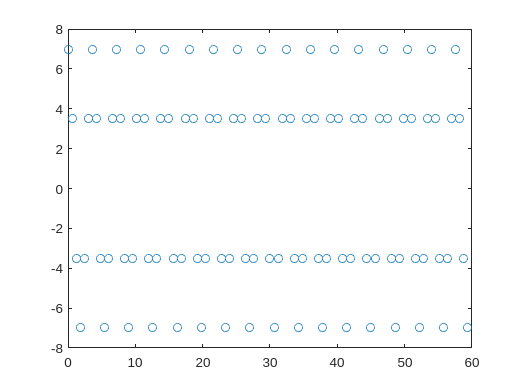

v0=4;
x_n=(v0*w)*cos(w*td);
figure(1)
plot(td,x_n,'o')

v=[x_n ;zeros(1,N)];
%velocidad del movil 1, y corresponde a la velocidad relativa de 1 respecto 3 y de 1 respecto 2.
%solo tiebe componente en x pues se considera la bisectriz del triangulo que esta alineada con el eje x
%siendo la velocidad de 3 respecto a 2 igual a cero dadao que los dos estan quietos

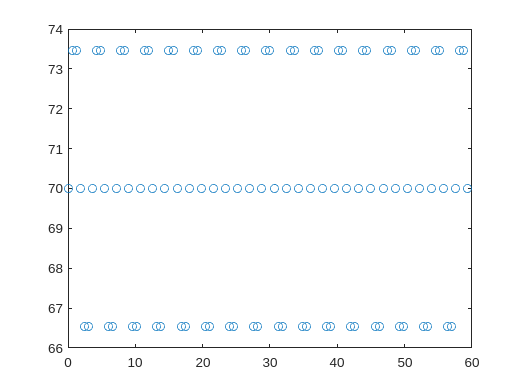

A=v0;
p_n=p0+A*sin(w*td);
figure(2)
plot(td,p_n,'o')

b=30%cm distancia entre robots o markers de la base del triangulo isosceles

b = 30

h=p_n;%altura del triangulo
a=sqrt(h.^2+ (b/2)^2);%lados iguales del triangulo isosceles

alpha123=asin(h./a);
alpha231=alpha123;
alpha312=(pi/2-alpha231).*2;
Dalpha123=diff(alpha123)./ts;
Dalpha312=diff(alpha312)./ts;
Dalpha231=diff(alpha231)./ts;
for i=2:N
 
    if Dalpha312(i-1) ~= 0
        m2_21=M2_21(alpha123(i),alpha312(i),alpha231(i),Dalpha231(i-1),Dalpha123(i-1),Dalpha312(i-1));
        m2_12=M2_12(alpha123(i),alpha312(i),Dalpha123(i-1),Dalpha312(i-1));
        m2_123=M2_123(alpha123(i),alpha231(i),Dalpha123(i-1),Dalpha231(i-1),m2_12,m2_21);
        M2_123_inv=inv(m2_123);
        pn=m2_123\[sin(alpha123(i))*(rot(alpha312(i))).'*v([1 2],i) - sin(alpha231(i))*v([1 2],i);sin(alpha312(i))*(rot(alpha231(i))).'*(-v([1 2],i))]
    
    end
end

pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn =   -88.6516
   18.9968
   88.6516
   18.9968


pn =   -42.2223
    9.5187
   42.2223
    9.5187


pn =   -80.6421
   17.2805
   80.6421
   17.2805


pn =   -42.4071
    8.6587
   42.4071
    8.6587


pn = 	1.0e+14 *

    3.6977
   -0.7550
   -3.6977
   -0.7550


pn = 4×1
  -88.6516
   18.9968
   88.6516
   18.9968


pn = 4×1
  -42.2223
    9.5187
   42.2223
    9.5187


pn = 4×1
  -80.6421
   17.2805
   80.6421
   17.2805


pn = 4×1
  -42.4071
    8.6587
   42.4071
    8.6587


pn = 4×1
  -88.6516
   18.9968
   88.6516
   18.9968


pn = 4×1
  -42.2223
    9.5187
   42.2223
    9.5187


pn = 4×1
  -80.6421
   17.2805
   80.6421
   17.2805


pn = 4×1
  -42.4071
    8.6587
   42.4071
    8.6587


pn = 4×1
  -88.6516
   18.9968
   88.6516
   18.9968


pn = 4×1
  -42.2223
    9.5187
   42.2223
    9.5187


pn = 4×1
  -80.6421
   17.2805
   80.6421
   17.2805


pn = 4×1
  -42.4071
    8.6587
   42.4071
    8.6587


pn = 4×1
  -88.6516
   18.9968
   88.6516
   18.9968


pn = 4×1
  -42.2223
    9.5187
   42.2223
    9.5187


pn = 4×1
  -80.6421
   17.2805
   80.6421
   17.2805


pn = 4×1
  -42.4071
    8.6587
   42.4071
    8.6587


pn = 4×1
	1.0e+14 *

    3.6977
   -0.7550
   -3.6977
   -0.7550


pn = 4×1
  -88.6516
   18.9968
   88.6516
   18.9968
